# DYSKR

%INPUTS___________________________________________
A = [0 1; -6 -5];
B = [0; 6];
C = [1 0];
D = 0;
x0 = [1; 1];
h = 0.1;
t = 0:0.1:2;
i_max = max(t/h);

syms t_s;
syms h_s
disp("Analityc solution")

Analityc solution


y = expm(A.*t_s)*x0

$$y = \left(\begin{array}{c} 4\,{\mathrm{e}}^{-2\,t_{s}}-3\,{\mathrm{e}}^{-3\,t_{s}}\\ 9\,{\mathrm{e}}^{-3\,t_{s}}-8\,{\mathrm{e}}^{-2\,t_{s}} \end{array}\right)$$

disp("Analityc dicrete matrix")

Analityc dicrete matrix


A_plus_s = expm(A.*h_s)

$$A\_plus\_s = \left(\begin{array}{cc} 3\,{\mathrm{e}}^{-2\,h_{s}}-2\,{\mathrm{e}}^{-3\,h_{s}} & {\mathrm{e}}^{-2\,h_{s}}-{\mathrm{e}}^{-3\,h_{s}}\\ 6\,{\mathrm{e}}^{-3\,h_{s}}-6\,{\mathrm{e}}^{-2\,h_{s}} & 3\,{\mathrm{e}}^{-3\,h_{s}}-2\,{\mathrm{e}}^{-2\,h_{s}} \end{array}\right)$$

B_plus_s = inv(A)*(expm(A*h_s) - eye(2, 2))*B

$$B\_plus\_s = \left(\begin{array}{c} 2\,{\mathrm{e}}^{-3\,h_{s}}-3\,{\mathrm{e}}^{-2\,h_{s}}+1\\ 6\,{\mathrm{e}}^{-2\,h_{s}}-6\,{\mathrm{e}}^{-3\,h_{s}} \end{array}\right)$$

A_plus = subs(A_plus_s, h_s, h);
%A_plus = double(A_plus)
B_plus = subs(B_plus_s, h_s, h);
%B_plus = double(B_plus)

syscmodel = ss(A, B, C, D);
sysdmodel = c2d(syscmodel,h);
disp("Discrete model")

Discrete model


A_discr = sysdmodel.A

A_discr =     0.9746    0.0779
   -0.4675    0.5850


B_discr = sysdmodel.B

B_discr =     0.0254
    0.4675


C_discr = sysdmodel.C

C_discr =      1     0


D_discr = sysdmodel.D

D_discr = 0

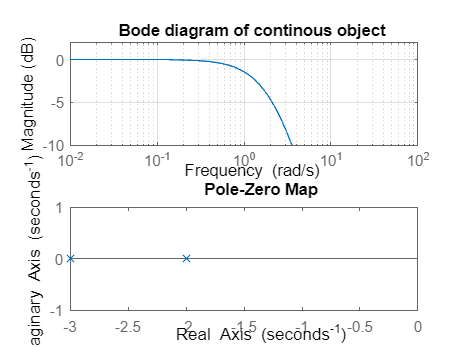


figure;
subplot(2, 1, 1)
opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.YLim={[-10 2]};
bode(syscmodel,opts1), grid on, hold all
title("Bode diagram of continous object")
subplot(2, 1, 2)
pzmap(syscmodel)

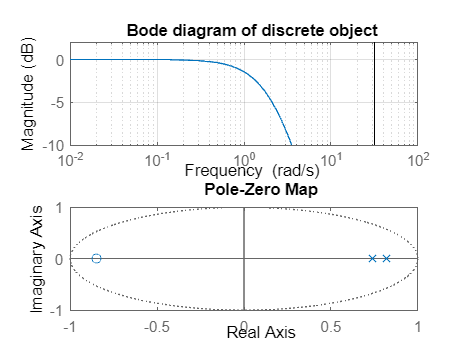


figure;
subplot(2, 1, 1)
opts1=bodeoptions('cstprefs');
opts1.PhaseVisible = 'off';
opts1.YLim={[-10 2]};
bode(sysdmodel,opts1), grid on, hold all
title("Bode diagram of discrete object")
subplot(2, 1, 2)
pzmap(sysdmodel)

Nomeric solving

euler_forw = @(A, h, x) (eye(2, 2) + h*A)*x; 
euler_back = @(A, h, x) ((eye(2, 2) - h*A)^-1)*x; 
NewtonColes = @(A, h, x) (eye(2, 2) + 0.5*h*A)*((eye(2, 2) - 0.5*h*A)^-1)*x;
y_num = double(subs(y, t_s, t))

y_num =     1.0000    1.0525    1.0348    0.9755    0.8937    0.8021    0.7089    0.6190    0.5354    0.4596    0.3920    0.3326    0.2809    0.2364    0.1983    0.1658    0.1384    0.1152    0.0957    0.0794    0.0658
    1.0000    0.1175   -0.4233   -0.7314   -0.8839   -0.9349   -0.9219   -0.8707   -0.7987   -0.7175   -0.6346   -0.5545   -0.4798   -0.4120   -0.3515   -0.2983   -0.2520   -0.2121   -0.1779   -0.1489   -0.1242


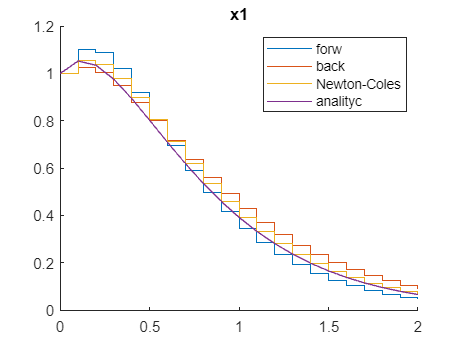


t_numh = 0:h:max(t);

x_forw = [];
x_forw(:, 1) = x0;
x_back = [];
x_back(:, 1) = x0;
x_NC = [];
x_NC(:, 1) = x0;

for i = 1:i_max
    x_forw(:, i+1) = euler_forw(A, h, x_forw(:, i));
    x_back(:, i+1) = euler_back(A, h, x_back(:, i));
    x_NC(:, i+1) = NewtonColes(A, h, x_NC(:, i));
end

figure
hold on;
stairs(t_numh, x_forw(1, :))
stairs(t_numh, x_back(1, :))
stairs(t_numh, x_NC(1, :))
plot(t, y_num(1, :))
legend(["forw", "back", "Newton-Coles", "analityc"])
title("x1")
hold off;